# Introdução Matlab

## Sobre Matlab

- Software da empresa Mathworks

- Ambiente para Computação Numérica

- Vetores e Matrizes

- Gráficos 2D e 3D

- Linguagem de Programação

- SIMULINK - Programação Gráfica de Sistemas

- Toolboxs diversos

- Aquisição e Processamento de Sinais

- Regressao Linear e Nao-Linear

- Resolução de Equações Diferenciais Parciais

- Projeto, Simulação e Controle de Sistemas

- Geração de Interface Gráfica (GUI)

- Computação Simbólica

- Data Science e Machine Learning

- e muito mais

### Software da empresa Mathworks

[MathWorks](https://www.mathworks.com/) é uma empresa privada americana especializada em software de computação matemática.

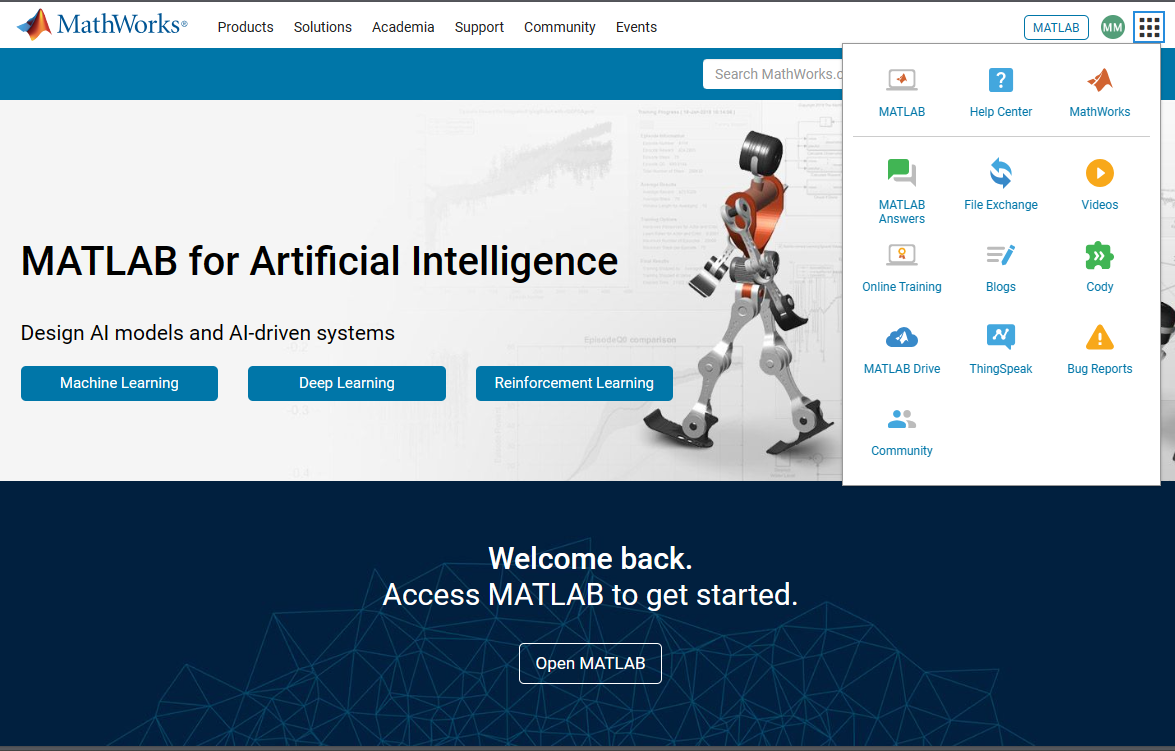

Seus principais produtos incluem MATLAB e Simulink, que suportam análise e simulação de dados.

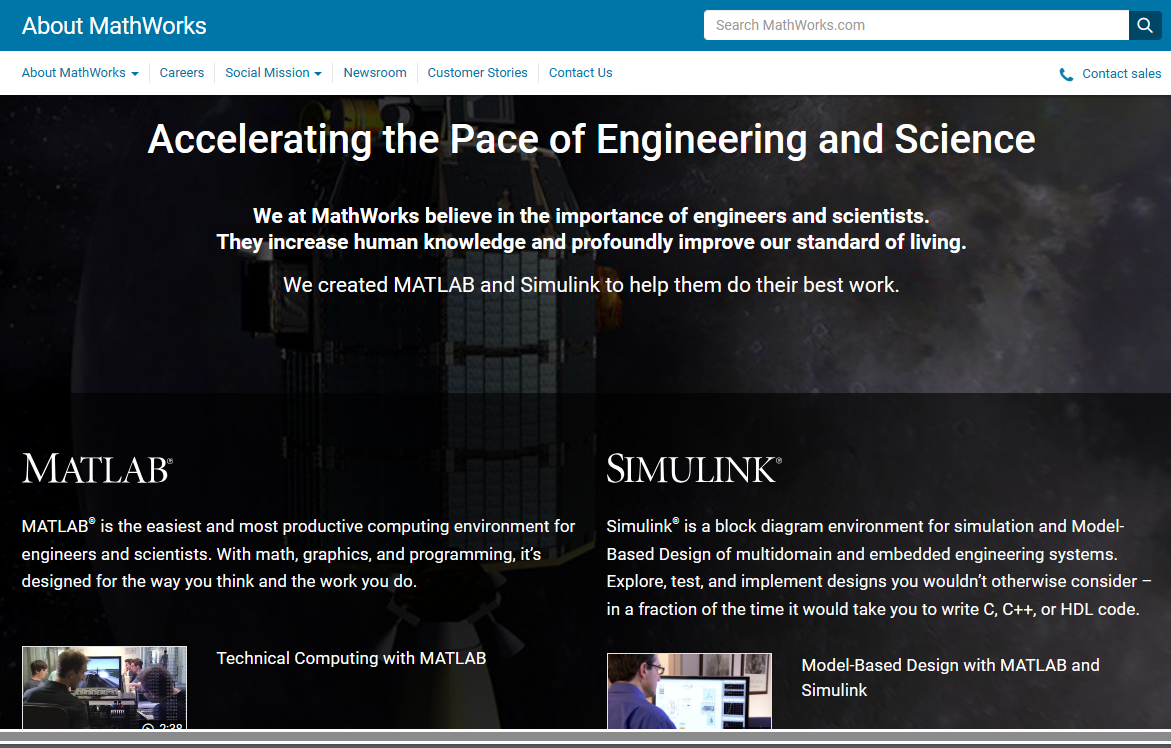

### Matlab Online

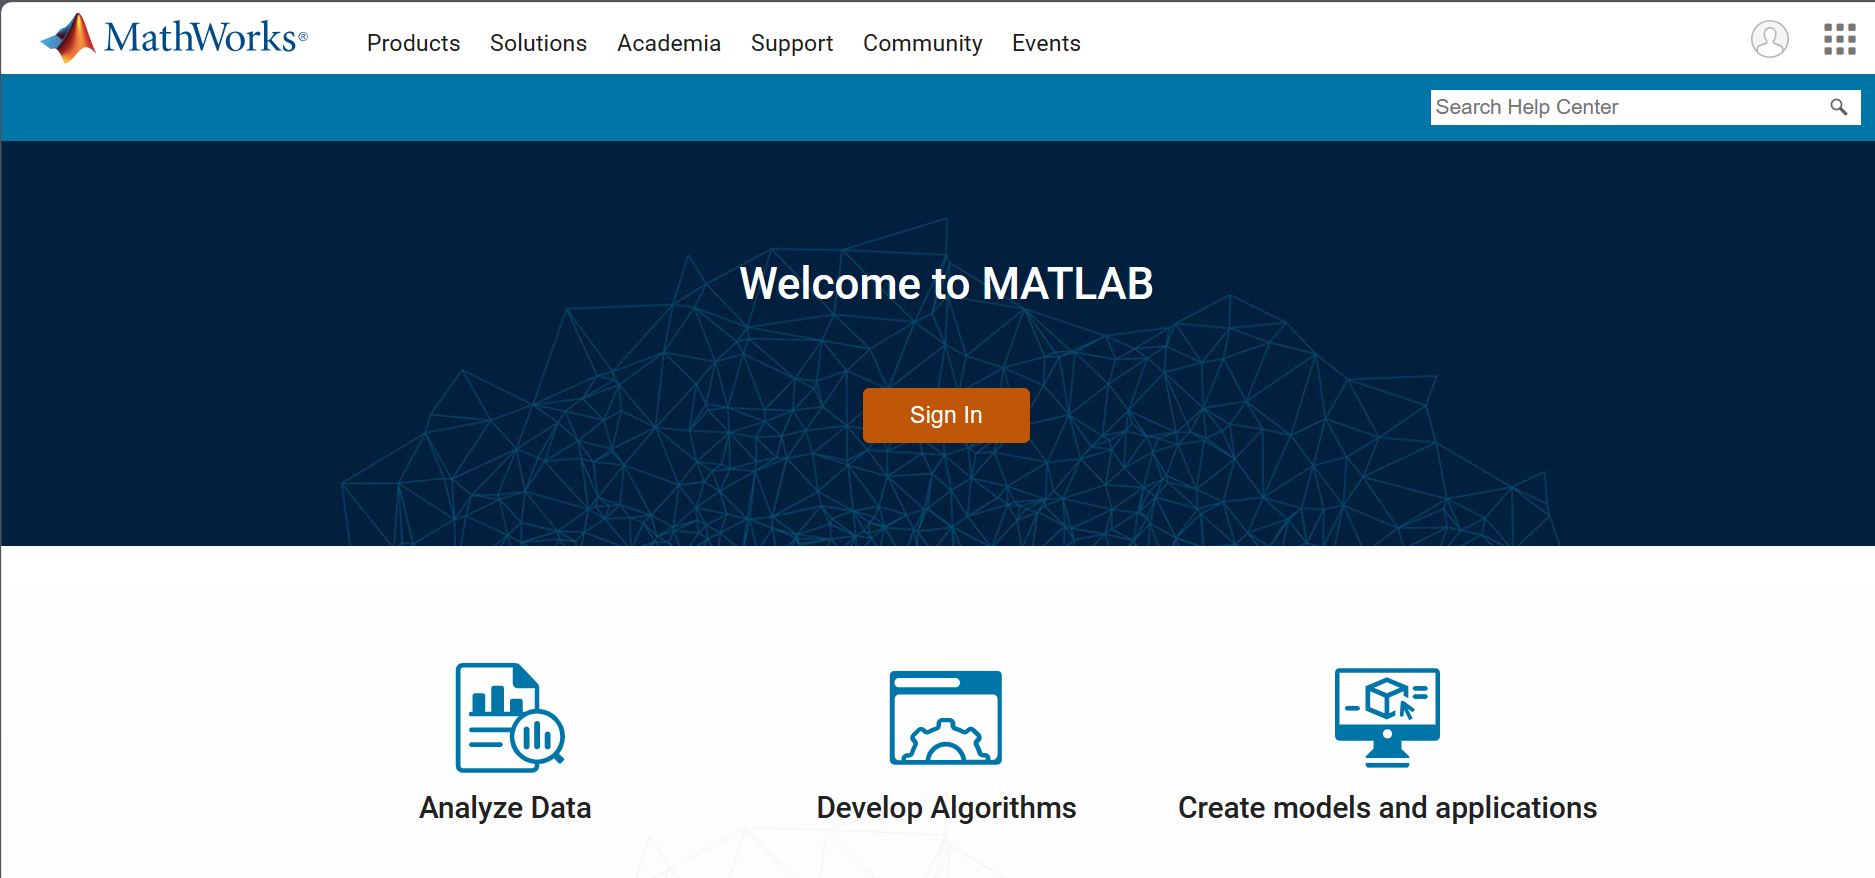

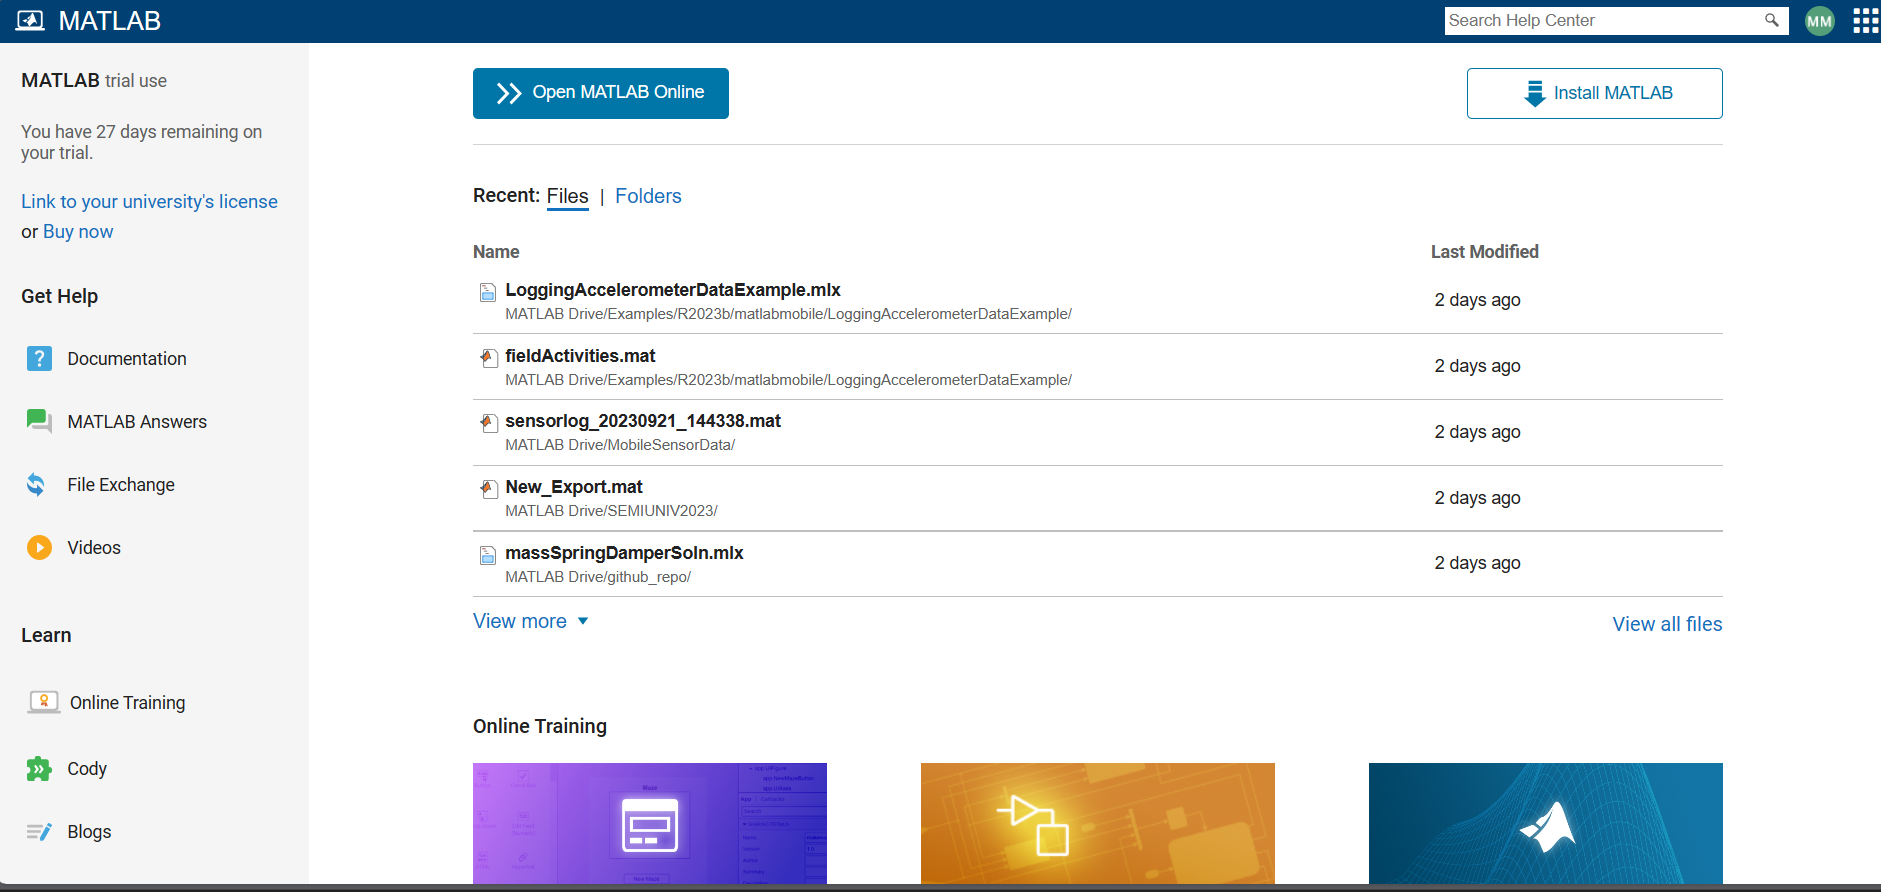

### Ambiente para Computação Numérica

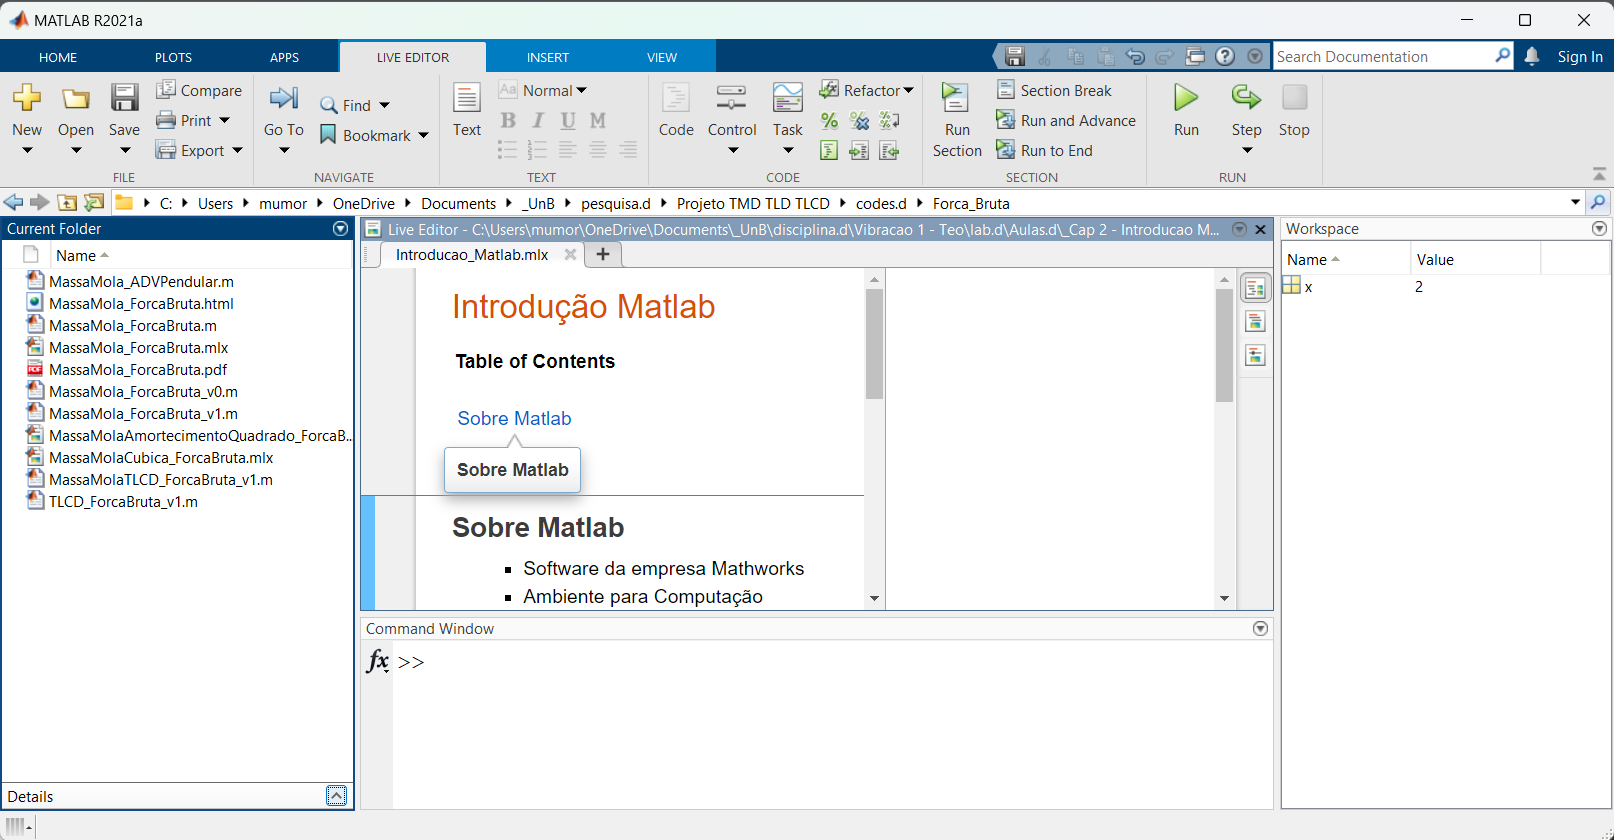

### Help - Documentação

A documentação no MatLab pode ser acessada diretamento no ambiente *Command Window* pelo comando `help`, por exemplo*:*

## Primeiros Comandos

Os comandos inicais para qualquer programa em Matlab são 

- o comando `clear` - limpar memória

**Vamos tentar?**

% limpar a memória
clear all
% fechar as telas gráficas
close all
% limpar a tela
clc

## Operações em `Matlab`

Em Matlab, as operações de adição, subtração, multiplicação e divisão em quantidades escalares são da seguinte forma:

***Use '***`Crlt+Enter`***' para executar as linhas de código abaixo:***

% Variaveis Definição
a = 6

a = 6

b = 2;
% Adição e Subtração
c = a+b ; 
d = a-b ;

% Multiplicação e Divisão
c = a*b ; 
d = a/b ; 

disp(['Multiplicação c = a*b = ',num2str(c)])

Multiplicação c = a*b = 12


disp(['Divisão d = a/b = ',num2str(d)])

Divisão d = a/b = 3


## Matrizes e Operações Matriciais em `Matlab`

Em Matlab, as operações matriciais de adição, subtração, multiplicação e divisão pode ser realizados de forma usual em quantidades escalares:

Mas também podem ser utilizados para manipular **vetores** e **matrizes**.

Por exemplo, a definição de uma pequena matriz A pode ser definida da seguinte forma:

***Vamos executar as linhas de código acima?***

Para operar as matrizes A e B, podemos fazer uma simples subtração:

***Vamos executar as linhas de código acima?***

Vc pode tentar outras operações:

***Vamos executar as linhas de código acima?***

## Geração Automática de Vetores e Matrizes

A geração automática de vetores deve ser realizada da seguinte forma:

***Vamos executar as linhas de código acima?***

Existem algum comandos de geração de vetores linearmente e logaritmicamente espaçados:

## Matrizes Especiais

Temos ainda algumas comandos especiais:

***Vamos executar as linhas de código acima?***

## Manipular Elementos de Matriz

Os elementos matriciais podem ser manipulados individualmente ou em blocos.

Por exemplo,

% seja as matrizes A e B
A = [1 3  5 ; ...
     1 0  1 ; ...
     5 0  9 ] ;
B = [1 3 51 ; ...
     2 6 12 ; ...
    10 7 28 ];

C = A+B
C(1,1) = 2*A(2,2) + B(3,3)

Ou criarmos submatrizes

E = C(1:2,2:3)

## Transposição de Matrizes

A transposição de matrizes é dada pelo comando transpose:

% transposição da matriz E
transpose(E)
% ou ainda,
% a forma mais usual - o comando ' (aspas - apostrofe)
E'

## Inversão de Matrizes Usando o Operador \

Seja um sistema de equações lineares,


$$\textrm{Ax}=b$$


onde $A$é a matriz quadrada de coeficientes, $b$ o vetor de forçamento, e $x$ o vetor de incógnitas.

A solução do sistema de equações lineares é obtida pelo comando `\` (barra invertida)

Trataremos um problema em Exemplo de Aplicação: Equação de Calor 1D.

## Funções

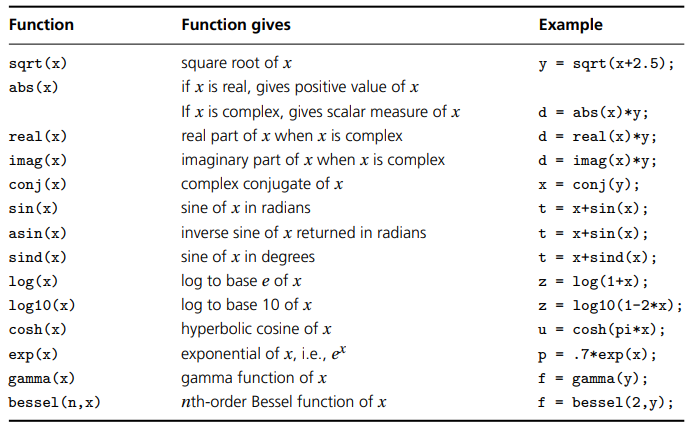

Seja as funções acima, podemos tentar as seguintes linhas de código:

***Vamos executar as linhas de código acima?***

## Gráficos 2D em Matlab

Uma das principais vantagens do Matlab, a plotagem de gráficos é dada pelo comando `plot(x,y)`, onde `x` e y são vetores representando ordenadas e abscisas, respectivamente.

Por exemplo:

 ***Vamos executar as linhas de código acima?***

OBS: Os simbolos e caracteres para a plotagem é descrito na tabela abaixo:

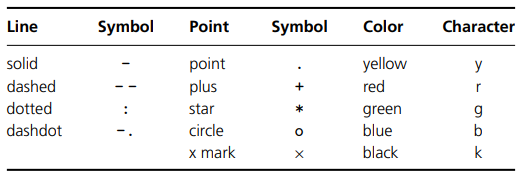

Existem outras formas de plotagem. Durante as apresentações a seguir, vamos discutir apenas alguns dos diversos tipos de plotagens. Em Insert/CODE/Task/Create Plot, podemos observar os diversos tipos de visualização gráfica disponíveis.

OBS: LEMBRAR DE UTILIZAR O GINPUT NO EXEMPLO DE APLICAÇÃO 

## Gráfico 3D em Matlab

## Exemplo de Aplicação: Equação de Calor 1D

Seja equação de calor 1D, 

$\frac{\partial \;\;}{\partial x}\left(k_x \;\frac{\partial \;\theta \;}{\partial x}\;\right)+\dot{q} =\rho \;C_p \frac{\partial \;\theta \;}{\partial t}\;$,

onde $\theta \;$é a temperatura $\left\lbrack \textrm{ºC}\right\rbrack$, $k_x$ a condutividade térmica, $C_p$ a condutividade térmica, e $\rho$ a densidade do material $\left\lbrack \textrm{kg}/m^3 \right\rbrack$.

No caso estacionário em material homogênio, a equação de calor toma a seguinte forma:

$\frac{\partial^2 \;\theta \;}{\partial x^2 }=0$, para o domínio $x\in \left\lbrack 0:L\right\rbrack$.

A representação em diferenças finitas da segunda derivada $\partial_x^2 \left(\ldotp \ldotp \ldotp \right)$é dada pela seguinte expressão:

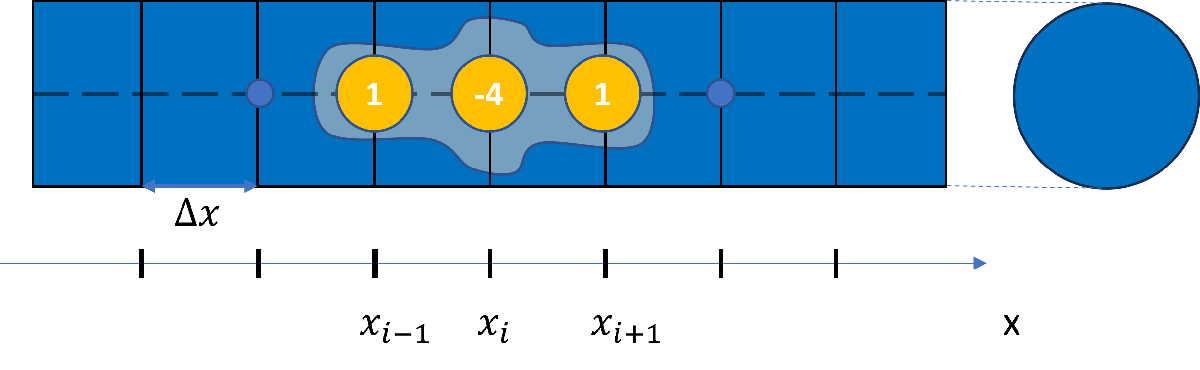

$\frac{\partial^2 \theta }{\partial x^2 }\simeq \frac{\;\theta_{x_i -\Delta x} -2\theta_{x_i } +\theta_{x_i +\Delta x} }{\Delta x^2 }=\frac{\;\theta_{i-1} -2\theta_i +\theta_{i+1} }{\Delta x^2 }$, onde $\Delta x=x\left(i\right)$

Logo, substituindo na equação de calor 1D estácionário, temos a sequinte equação:

$\frac{\;\theta_{i-1} -2\theta_i +\theta_{i+1} }{\Delta x^2 }=0$, 

ou ainda,

$\;\theta_{i-1} -2\theta_i +\theta_{i+1} =0$, para $x_i =\left\lbrack 0,\;\Delta x,\;\;2\Delta x,\;\;3\Delta x,\dots ,n\Delta x,\left(n+1\right)\Delta x\right\rbrack$ onde, o comprimento da barra $L=n\Delta x$.

### Montagem da matriz tridiagonal

A matriz tridiagonal representa a equação de calor 1D estácionário em diferenças finitas.

A construção da matriz tridiagonal, para $N=6$ , é dada pela seguintes linhas de código:

***Vamos executar as linhas de código acima?***

%% Matriz Tridiagonal 7x7
m = 6;
M = diag(ones(m,1),-1) - 2*diag(ones(m+1,1)) + diag(ones(m,1),+1)

Logo, a equação de calor 1D estácionário em diferenças finitas apresenta a seguinte forma matricial:

$\left\lbrack \begin{array}{ccccccc}
-2 & 1 &  &  &  &  & \\
1 & -2 & 1 &  &  &  & \\
 & 1 & -2 & 1 &  &  & \\
 &  & 1 & -2 & 1 &  & \\
 &  &  & 1 & -2 & 1 & \\
 &  &  &  & 1 & -2 & 1\\
 &  &  &  &  & 1 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\theta_3 \\
\theta_4 \\
\theta_5 \\
\theta_6 \\
\theta_7 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$, ou ainda, $M\;\theta =0$,

### Condições de Contorno

O problema de equação de calor 1D estacionário abaixo apresenta a seguintes condições de contorno de temperatura impostos:

- $\theta_1 =\theta \left(x=0\right)=100ºC$, e

- 
$$\theta_7 =\theta \left(x=L\right)=\;10ºC$$


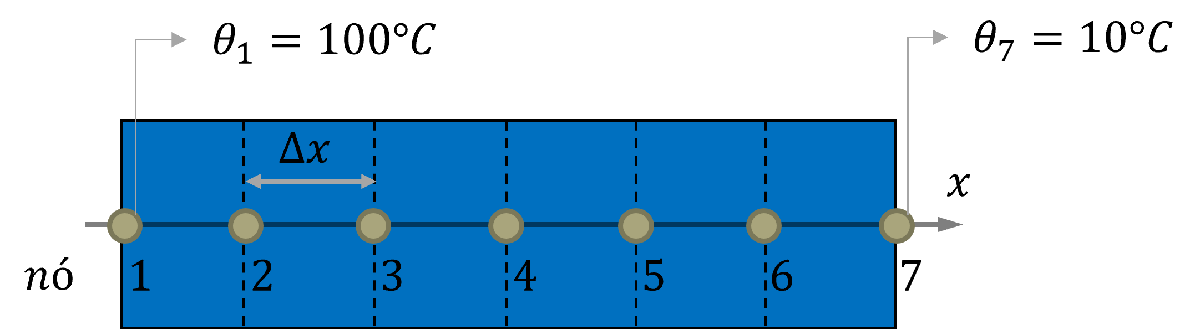

Para aplicarmos na seguinte condições de contorno acima, temos de realizar as seguinte linhas de código:

***Vamos executar as linhas de código acima?***

%% Condições de Contorno
% temperatura importa - \theta(x = 0) = 100
M(1,1) = 100 ;

C =      2     6    56
     3     6    13
    15     7    37


%M(2:7,1) = 0   ;

C =     28     6    56
     3     6    13
    15     7    37


M(1,2:7) = 0   ;
disp(M)

E =      6    56
     6    13


% temperatura importa - \theta(x = L) = 10
M(7,7) = 10 ;
%M(1:6,7) = 0   ;
M(7,1:6) = 0   ;
disp(M)

ans =      6     6
    56    13


### Montagem da Matriz Global e Solução do Sist. Linear

Manipulando a equação de calor 1D, temos que a equação $M\theta =0$, pode ser reescrita da seguinte forma:

$\left\lbrack \begin{array}{ccccccc}
1 &  &  &  &  &  & \\
1 & 2 & 1 &  &  &  & \\
 & 1 & 2 & 1 &  &  & \\
 &  & 1 & 2 & 1 &  & \\
 &  &  & 1 & 2 & 1 & \\
 &  &  &  & 1 & 2 & 1\\
 &  &  &  &  &  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\theta_3 \\
\theta_4 \\
\theta_5 \\
\theta_6 \\
\theta_7 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
100\\
0\\
0\\
0\\
0\\
0\\
10
\end{array}\right\rbrack$, ou ainda,

$\;\theta_1 =100$, $\;\theta_7 =10$

Já as outras incógintas $\theta_2$ até $\theta_6$ são modeladas matricialmente, conforme equação abaixo:

 
$$\left\lbrack \begin{array}{ccccc}
2 & 1 &  &  & \\
1 & 2 & 1 &  & \\
 & 1 & 2 & 1 & \\
 &  & 1 & 2 & 1\\
 &  &  & 1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_2 \\
\theta_3 \\
\theta_4 \\
\theta_5 \\
\theta_6 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\theta_1 \\
0\\
0\\
0\\
-\theta_7 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-100\\
0\\
0\\
0\\
-10
\end{array}\right\rbrack$$


***Logo, para realizar essa operação temos de executar o seguinte código:***

***Vamos executar as linhas de código acima?***

M1=M(2:6,2:6);

ans =      6     6
    56    13


F1 = [-100  0*(1:3) -10 ]';
theta1 = M1\F1;
theta = [100 theta1' 10]'

### Plotagem do Campo de Temperatura

Para visualizar a solução do campo de temperatura $\theta \left(x\right),x\in \left\lbrack 0:L\right\rbrack$, podemos realizar as seguinte linhas de comando:

% plotagem
dx = 1/(7-1) ; % passo de malha
x = 0:dx:1 ;

plot(x,theta,'ro-')
xlabel('posição [m]')
ylabel('temperatura [ºC]')
legend('DF - malha dx=1/6')

## Lecture 1 - Comentários Finais

bla bla bla

M =     -2     1     0     0     0     0     0
     1    -2     1     0     0     0     0
     0     1    -2     1     0     0     0
     0     0     1    -2     1     0     0
     0     0     0     1    -2     1     0
     0     0     0     0     1    -2     1
     0     0     0     0     0     1    -2


   100     0     0     0     0     0     0
     1    -2     1     0     0     0     0
     0     1    -2     1     0     0     0
     0     0     1    -2     1     0     0
     0     0     0     1    -2     1     0
     0     0     0     0     1    -2     1
     0     0     0     0     0     1    -2



   100     0     0     0     0     0     0
     1    -2     1     0     0     0     0
     0     1    -2     1     0     0     0
     0     0     1    -2     1     0     0
     0     0     0     1    -2     1     0
     0     0     0     0     1    -2     1
     0     0     0     0     0     0    10



theta =   100.0000
   85.0000
   70.0000
   55.0000
   40.0000
   25.0000
   10.0000